# Digital image processing using MATLAB

## Image reading and display

- ".mat" files 

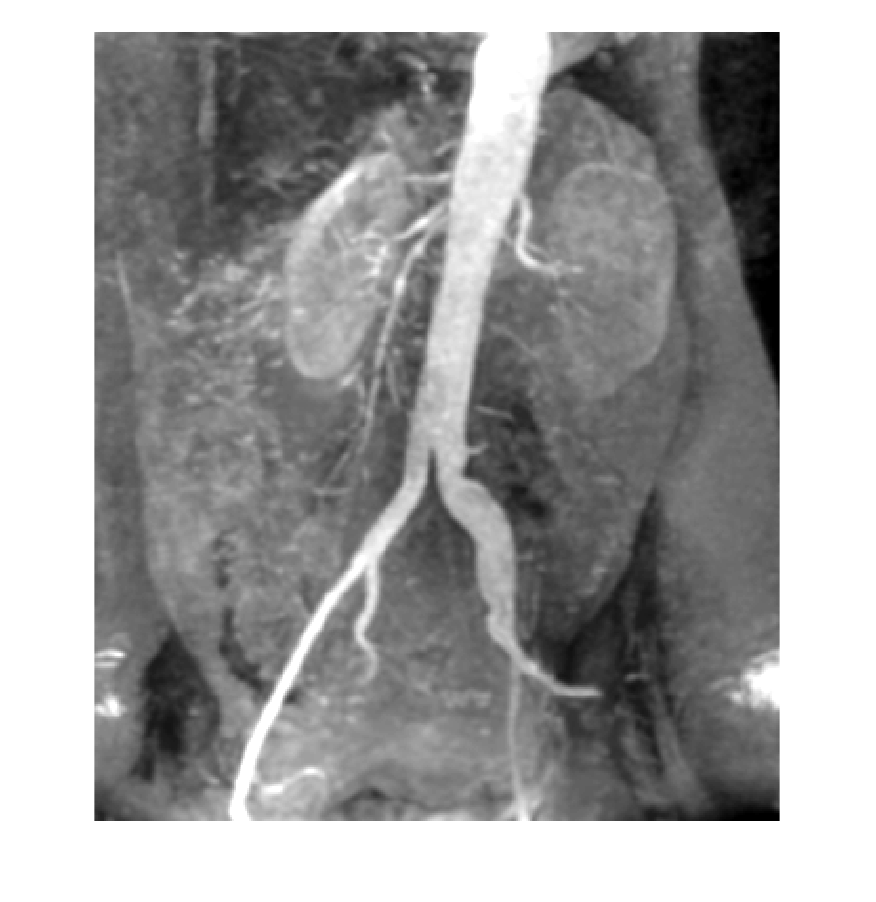

clear all;
clf; % clear current figure window
load Matlab_DIP_Tutorial\imagereading.mat % read the input image
figure(1);imshow(imagereading); % display the image

- picture files

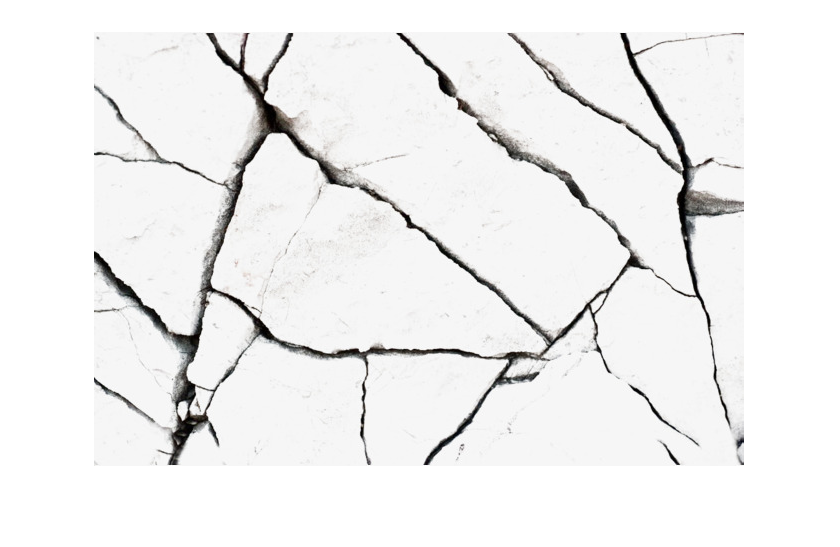

clf;
img_read = imread('Matlab_DIP_Tutorial\image1.jpg'); % read the input image
figure(2);imshow(img_read);

#### some helpful functions 

- title()

- axis()

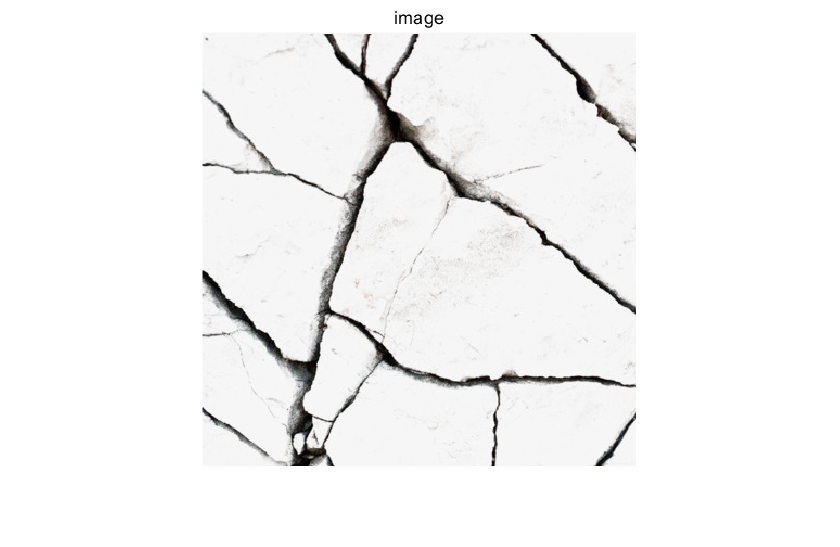

figure(3);imshow(img_read);
title('image'); % add a title to the image
axis([0 400 0 400]); % specify the range of the image display

- subplot()

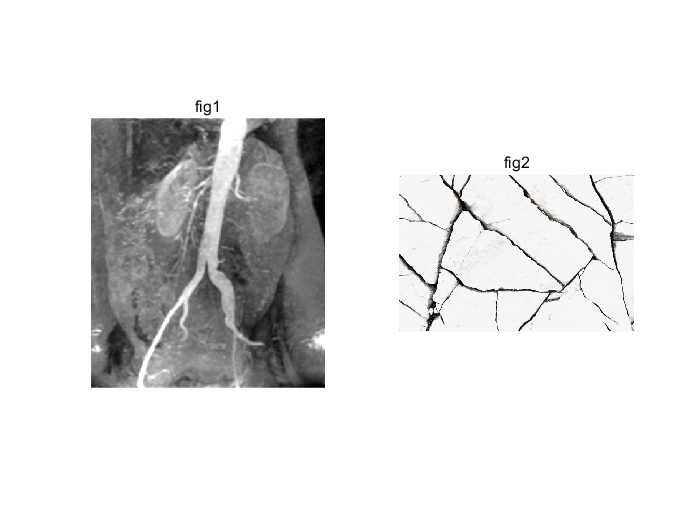

% Using subplot to split figure .
% Hence, we can show more than one image in the same figure.
figure(4);
subplot(1,2,1);
imshow(imagereading);title('fig1');
subplot(1,2,2);
imshow(img_read);title('fig2');

## Data type

- uint8 & double

- double()

- im2double()

- uint8()

- im2uint8()

clf;
camaraman = imread('Matlab_DIP_Tutorial\cameraman.tif'); % uint8 data
% both functions below turn 'uint8' type data into 'double' type data
img_a = double(camaraman); % double() keeps at a range of [0,255]
img_a

img_a =    156   159   158   155   158   156   159   158   157   158   158   159   160   160   160   158   163   161   162   160   164   160   165   163   161   163   161   164   165   162   161   165   165   164   166   165   164   166   167   165   165   164   170   166   167   167   170   168   169   166
   160   154   157   158   157   159   158   158   158   160   155   156   159   158   160   157   165   159   161   158   162   162   161   163   159   162   164   163   164   165   169   164   163   165   161   163   165   168   167   165   164   163   169   169   169   170   170   169   170   170
   156   159   158   155   158   156   159   158   157   158   158   159   160   160   160   158   163   161   162   160   164   160   165   163   161   163   161   164   165   162   161   165   165   164   166   165   164   166   167   165   165   164   170   166   167   167   170   168   169   166
   160   154   157   158   157   159   158   158   158   160   155   156   159   158   16

img_b = im2double(camaraman); % im2double() turn the range to [0,1]
img_b

img_b =     0.6118    0.6235    0.6196    0.6078    0.6196    0.6118    0.6235    0.6196    0.6157    0.6196    0.6196    0.6235    0.6275    0.6275    0.6275    0.6196    0.6392    0.6314    0.6353    0.6275    0.6431    0.6275    0.6471    0.6392    0.6314    0.6392    0.6314    0.6431    0.6471    0.6353    0.6314    0.6471    0.6471    0.6431    0.6510    0.6471    0.6431    0.6510    0.6549    0.6471    0.6471    0.6431    0.6667    0.6510    0.6549    0.6549    0.6667    0.6588    0.6627    0.6510
    0.6275    0.6039    0.6157    0.6196    0.6157    0.6235    0.6196    0.6196    0.6196    0.6275    0.6078    0.6118    0.6235    0.6196    0.6275    0.6157    0.6471    0.6235    0.6314    0.6196    0.6353    0.6353    0.6314    0.6392    0.6235    0.6353    0.6431    0.6392    0.6431    0.6471    0.6627    0.6431    0.6392    0.6471    0.6314    0.6392    0.6471    0.6588    0.6549    0.6471    0.6431    0.6392    0.6627    0.6627    0.6627    0.6667    0.6667    0.6627    0.6667 

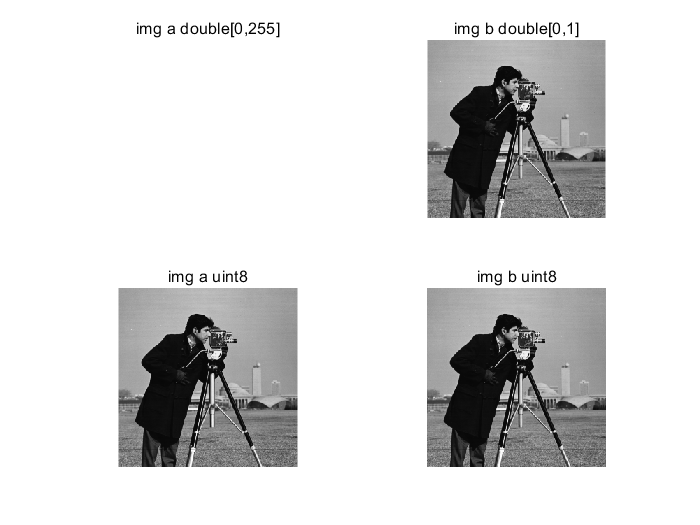

% When we use imshow to display the image, we must pay attention to the data
% type. If the image is 'double' type, then only when it's normalized, it
% can be shown by function 'imshow()', which means the 'double' type data
% must at a range of [0,1].
% If the data is at range [0,255], we must turn its type into 'uint8'.
% function'double()' ---invert---function'uint8()'
% function'im2double()'---invert---function'im2uint8()'
figure(5);
subplot(2,2,1);imshow(img_a);title('img a double[0,255]');
subplot(2,2,2);imshow(img_b);title('img b double[0,1]');
subplot(2,2,3);imshow(uint8(img_a));title('img a uint8');
subplot(2,2,4);imshow(im2uint8(img_b));title('img b uint8');

## RGB image

- How to split three color channels?

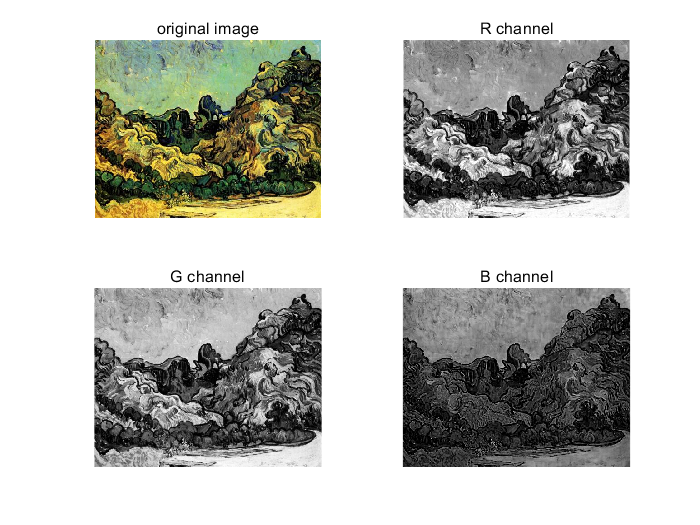

clf;
original_img = imread('Matlab_DIP_Tutorial\image2.jpg');% Read the input image, here the image is a 3-D matrix.
img_R = original_img(:,:,1);% Get the data of R channel. Note that img_R is a 2-D matrix.
img_G = original_img(:,:,2);% Get the data of G channel. Note that img_G is a 2-D matrix.
img_B = original_img(:,:,3);% Get the data of B channel. Note that img_B is a 2-D matrix.
figure(6);
subplot(2,2,1);imshow(original_img);title('original image');
subplot(2,2,2);imshow(img_R);title('R channel');
subplot(2,2,3);imshow(img_G);title('G channel');
subplot(2,2,4);imshow(img_B);title('B channel');

The R,G,B channel's images are all gray. For a single channel image, each pixel only records its intensity. There is no color imformation for a graylevel image. When we concatenate all the channels, each channel will be defined as a R/G/B channel,which means they have color imformation. That's why three gray images can become a color image. 

- How to concatenate three color channels?

- cat()

clf;
%img_R

img_R = 394×500 uint8 矩阵
   144   139   131   142   128    99   109   120   141   121   122   132   142   180   224   231   209   163   195   202   195   238   189   170   190   192   172   173   157   132   154   161   159   156   153   150   147   148   151   153   163   142   150   152   154   163   168   175   146   158
   137   143   126   116   107    98   104    92   127   115   125   136   140   171   215   224   202   169   195   201   200   236   184   173   195   197   180   177   163   146   163   164   152   150   149   148   146   148   151   153   155   156   160   149   154   162   174   154   138   148
   123   145   145   142   128   112   107    84   115   111   128   140   137   164   205   215   186   173   191   193   199   223   168   167   189   191   174   164   156   151   161   155   146   145   144   145   146   149   151   152   151   159   158   153   161   144   168   137   129   138
    98   117   131   145   131   101   102   104   118   112   127   137

%img_G

img_G = 394×500 uint8 矩阵
   169   158   141   143   124    95   109   129   162   149   154   160   160   186   217   224   212   172   200   205   195   236   186   168   187   192   178   187   175   158   184   196   197   196   192   189   187   187   190   192   199   178   182   183   182   190   191   196   163   172
   162   162   136   119   103    94   106   101   148   143   157   164   158   178   208   216   207   178   203   206   200   236   181   170   194   200   186   190   183   172   193   198   190   189   188   186   185   187   189   191   191   189   192   179   182   189   197   175   155   162
   148   164   155   145   125   109   108    94   136   139   160   168   156   171   202   211   190   182   198   198   201   225   166   166   189   195   182   178   177   178   193   191   181   180   182   182   184   187   189   189   186   192   189   183   188   170   190   157   145   152
   123   138   143   150   129    99   106   114   139   140   158   165

%img_B

img_B = 394×500 uint8 矩阵
   140   126   104   101    77    50    73   100   145   137   143   146   136   152   173   172   157   115   142   148   141   185   143   130   156   164   150   154   135   110   130   142   156   162   161   162   161   166   171   174   185   164   167   168   167   173   175   179   145   157
   133   130    99    76    58    49    69    74   131   131   146   150   134   145   164   167   153   121   146   150   146   186   138   135   164   173   160   160   146   127   141   148   153   160   161   161   164   168   174   176   179   178   179   167   168   174   181   160   139   147
   118   132   118   102    80    66    74    67   119   127   149   154   134   138   159   163   139   129   144   144   151   178   127   135   163   172   159   152   144   137   146   147   151   158   161   164   169   174   178   181   179   185   181   175   179   159   178   145   132   137
    94   107   107   110    88    60    73    89   122   128   150   151

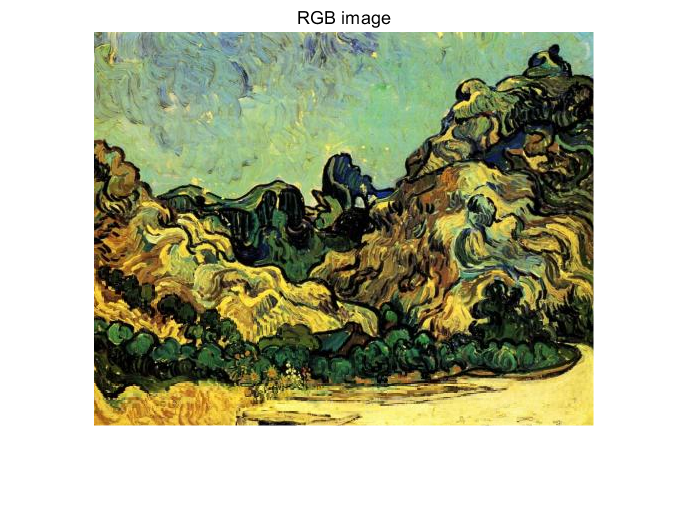

result = cat(3,img_R,img_G,img_B);
figure(7);imshow(result);title('RGB image');

xlim([1 501])
ylim([1 395])

## Some useful functions for this homework

- mean(): find the average value of input

A = [0,1,2;3,4,5;6,7,8] % define a 3*3 matrix

A =      0     1     2
     3     4     5
     6     7     8


average_A_col = mean(A) % function 'mean()' gives out the average of each column

average_A_col =      3     4     5


average_A_row = mean(A,2)% give dim=2 to calculate the average of each row

average_A_row =      1
     4
     7


average_A = mean(mean(A)) % If we want the average value of matrix A, we can use 'mean()' two times.

average_A = 4

average_a = x % Another way to get the average value of matrix A.

average_a = 4

- sort():the arrangement of data in a prescribed sequence

B = [0,7,6;3,5,4;1,8,2] % define a 3*3 matrix

B =      0     7     6
     3     5     4
     1     8     2


new_B_col = sort(B) % sort matrix B in each column (dim=1)(defalt dimension is 1)

new_B_col =      0     5     2
     1     7     4
     3     8     6


new_B_row = sort(B,2) % sort matrix B in each row (dim=2)

new_B_row =      0     6     7
     3     4     5
     1     2     8


new_B_all = sort(B(:)) % sort all the elements in matrix B

new_B_all =      0
     1
     2
     3
     4
     5
     6
     7
     8


new_B_all' % the symbol ' is used to find the transpose of matrix new_B_all

ans =      0     1     2     3     4     5     6     7     8


new_B_h2l = sort(B(:),'descend'); % 'descend' defines the sort direction (high to low)
new_B_h2l'

ans =      8     7     6     5     4     3     2     1     0


- round():find the nearest integer

C = 1.33;D = 6.67;
round_C = round(C)

round_C = 1

round_D = round(D)

round_D = 7

E = [2.11 3.5; -3.5 0.78];
round_E = round(E)

round_E =      2     4
    -4     1


- cumsum():cumulative sum

F = [1,4,7;2,5,8;3,6,9] % define a 3*3 matrix F

F =      1     4     7
     2     5     8
     3     6     9


cumsum_F_col = cumsum(F) % do the cumulative sum of each column

cumsum_F_col =      1     4     7
     3     9    15
     6    15    24


cumsum_F_row = cumsum(F,2) % do the cumulative sum of each row

cumsum_F_row =      1     5    12
     2     7    15
     3     9    18


cumsum_F_all = cumsum(F(:));% do the cumulative sum of all the elements in F
cumsum_F_all'

ans =      1     3     6    10    15    21    28    36    45


## Examples of digital image processing

- Addition of images

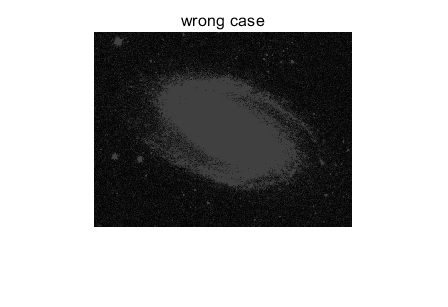

clear all;clf;clc;
Noise1 = imread('Matlab_DIP_Tutorial\Noisy_image1.jpg');
Noise2 = imread('Matlab_DIP_Tutorial\Noisy_image2.jpg');
Noise3 = imread('Matlab_DIP_Tutorial\Noisy_image3.jpg');
Noise4 = imread('Matlab_DIP_Tutorial\Noisy_image4.jpg');

% Wrong Case!
wrong_case = (Noise1 + Noise2 + Noise3 + Noise4)/4;
figure(8);imshow(wrong_case);title('wrong case');

Four original images are all uint8 data type.  When we add them, some of the addition result are larger than 255. However, the value of the intensity cannot larger than 255. Hence, we have to do division first and then add them.

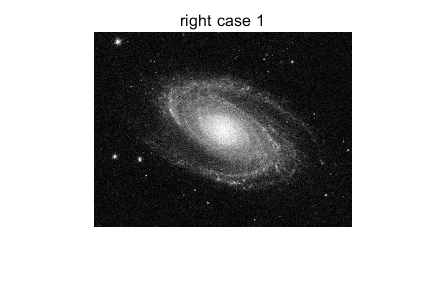

% Right Case!
right_case1 = Noise1/4 + Noise2/4 + Noise3/4 + Noise4/4;
figure(9);imshow(right_case1);title('right case 1');

Here gives another way to do addition by changing data type. 

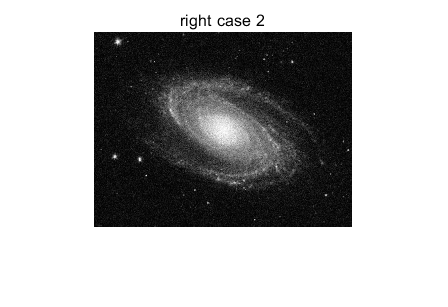

right_case2 = (double(Noise1) + double(Noise2) + double(Noise3) + double(Noise4))/4;
figure(10);imshow(uint8(right_case2));title('right case 2');

- Subtraction of images

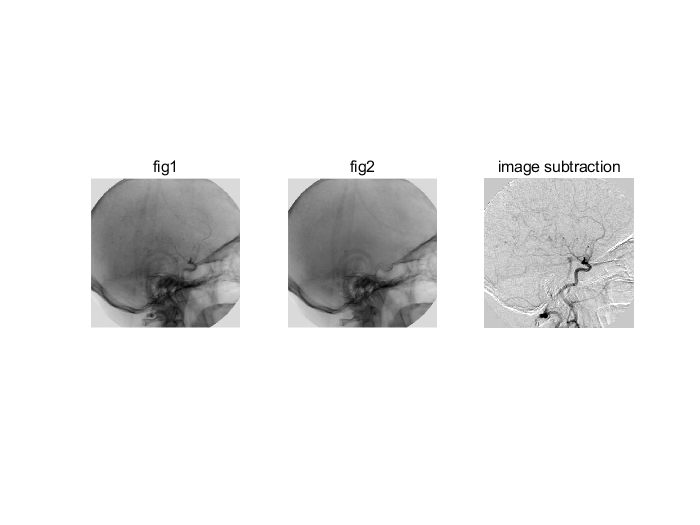

clear all;clf;
fig1 = imread("Matlab_DIP_Tutorial\Fig1.tif");
fig2 = imread("Matlab_DIP_Tutorial\Fig2.tif");
details = double(fig1)-double(fig2); % Using subtraction to find details in two similar images
n = 4; % Gain of details. (Larger value for higher contrast details)
background = 200; % intensity of the image background
result = background+n*(details); % Synthesize a new image
figure(11);
subplot(1,3,1);imshow(fig1);title('fig1');
subplot(1,3,2);imshow(fig2);title('fig2');
subplot(1,3,3);imshow(uint8(result));title('image subtraction')

- Multiplication of images

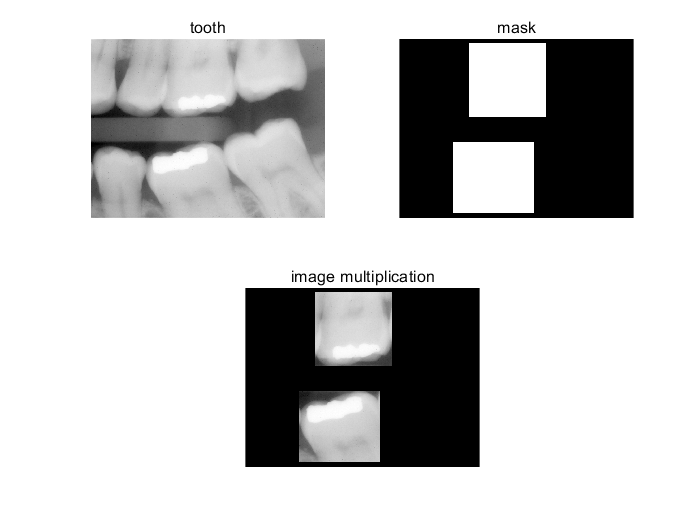

clear all;clf;
tooth = imread('Matlab_DIP_Tutorial\tooth.tif');
mask = imread('Matlab_DIP_Tutorial\mask.tif');

% Similarly as the addtion part, we cannot do multiplication directly.
% Here only shows one of the method to do multiplication.
% You can try the method of changing data type.

normalized_mask = mask/255; % Do the normalization of the mask.
result = tooth.*normalized_mask; % Then do the multiplication.
figure(12);
subplot(2,2,1);imshow(tooth);title('tooth');
subplot(2,2,2);imshow(mask);title('mask');
subplot(2,2,[3,4]);imshow(result);title('image multiplication');

- Division of images

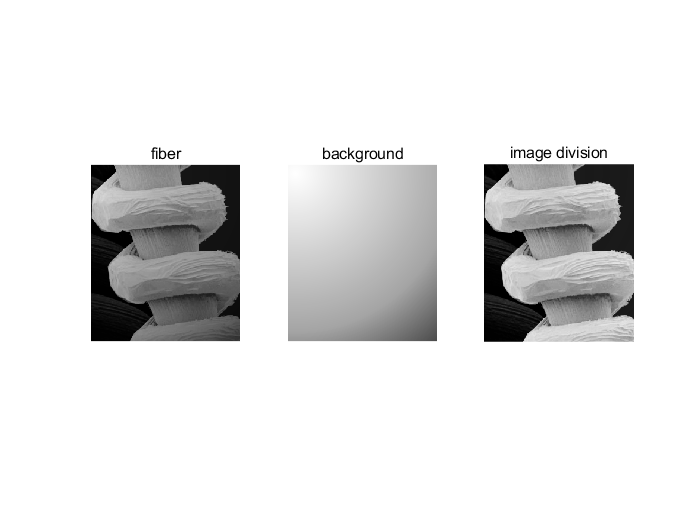

clear all;clf;
fiber = imread('Matlab_DIP_Tutorial\fiber.tif');
background = imread('Matlab_DIP_Tutorial\bkg.tif');

result = double(fiber)./double(background); % Do the division in 'double' data type.
figure(13);
subplot(1,3,1);imshow(fiber);title('fiber');
subplot(1,3,2);imshow(background);title('background');
subplot(1,3,3);imshow(result);title('image division');

- Background removal

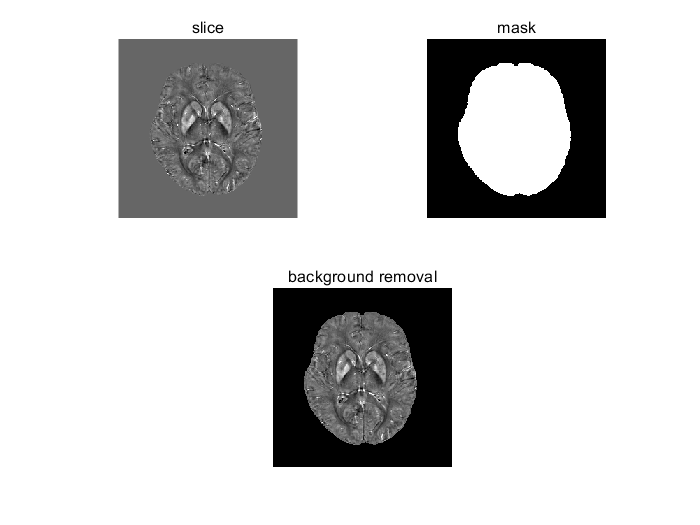

clear all;clf;
load Matlab_DIP_Tutorial\slice.mat slice
load Matlab_DIP_Tutorial\mask.mat mask

% There are also many ways to achieve this result.
% Here only shows one method to remove background.
% For different input data, the method of processing may also be different.

n = 5; % Gain of the input details to reach higher contrast. 
background = 0.4; % Since the input slice data is not all positive, we add a background to the slice.
new_slice = n*slice + background;
removal_bkg = new_slice.*double(mask); % Using mask to remove the useless background.

figure(14);% note the data type & data range,we should use function 'im2uint8()' here.
subplot(2,2,1);imshow(im2uint8(new_slice));title('slice'); 
subplot(2,2,2);imshow(mask*255);title('mask');
subplot(2,2,[3,4]);imshow(im2uint8(removal_bkg));title('background removal');